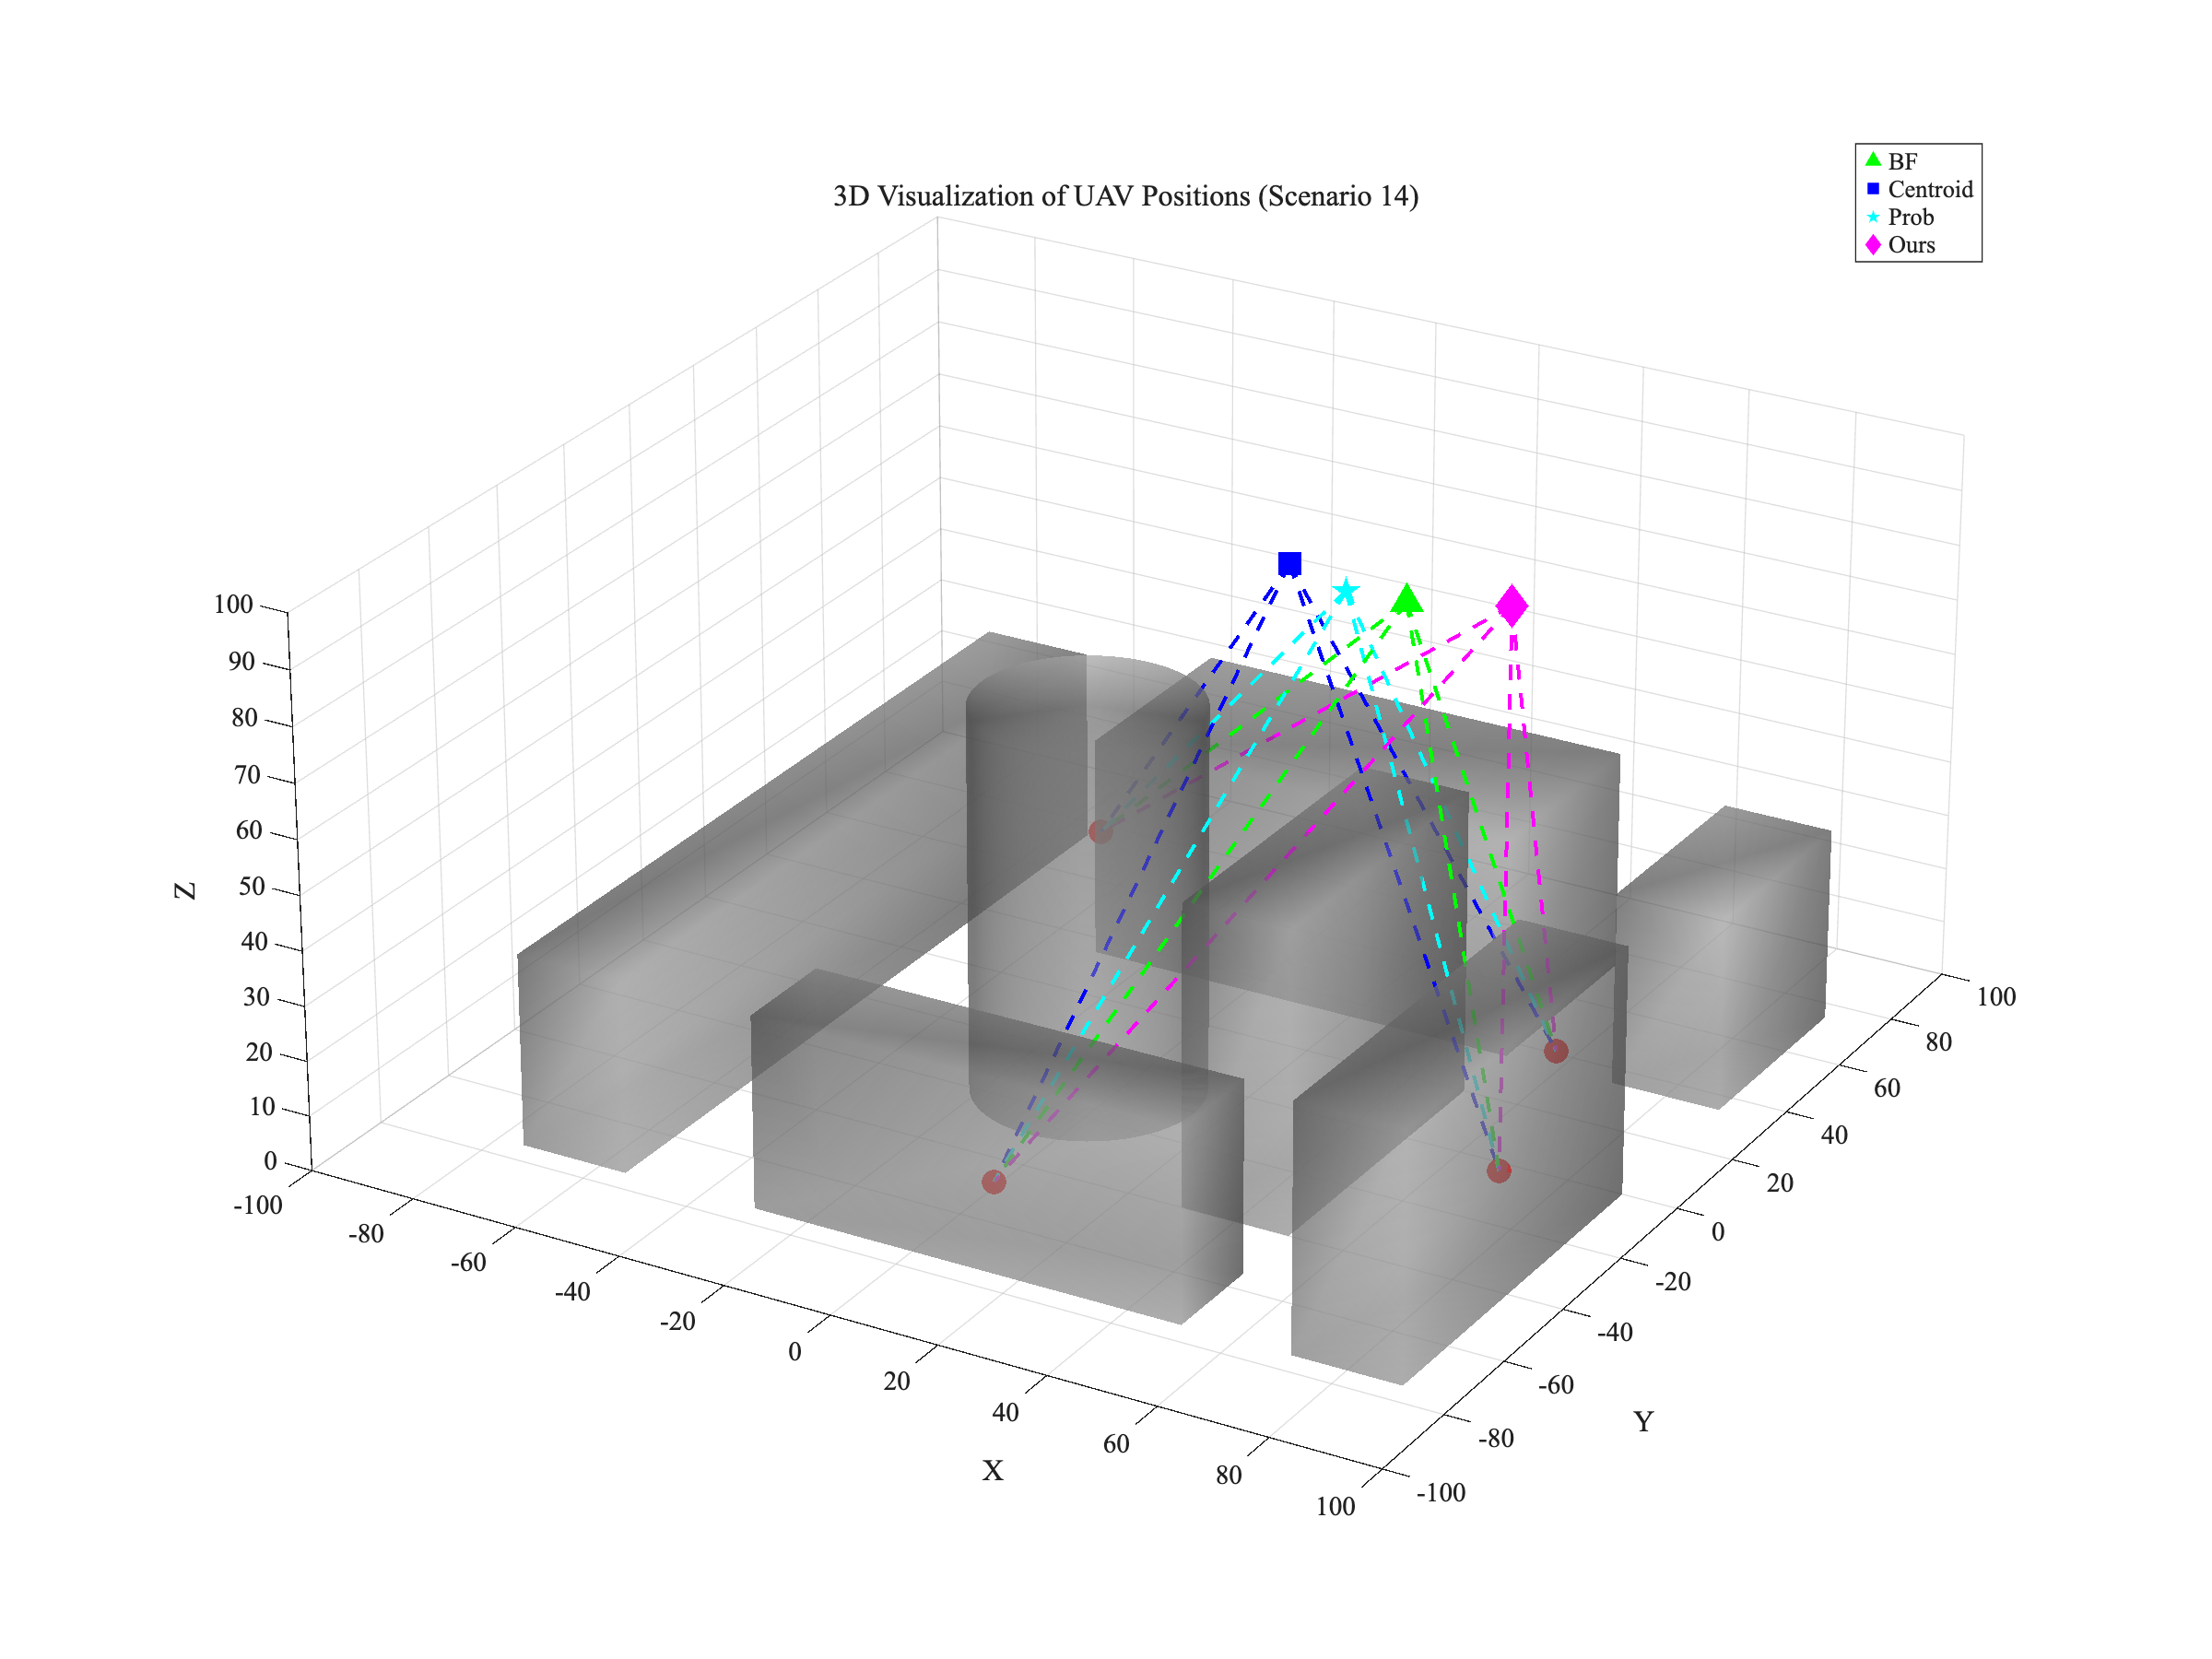

%% 1. 초기 설정
clear; clc; close all;

% 시각화할 데이터 행 선택 (MATLAB은 1부터 시작)
scenario_index = 14;

%% 2. 데이터 로드 및 추출
% CSV 파일 읽기
data_table = readtable('eval_mode_height_U4_H90.csv');
data_row = data_table(scenario_index, :);

% 지상 사용자(GUs) 좌표 추출 및 3x4 행렬로 변환
gnd_coords = [data_row.gnd1_x, data_row.gnd1_y, data_row.gnd1_z;
              data_row.gnd2_x, data_row.gnd2_y, data_row.gnd2_z;
              data_row.gnd3_x, data_row.gnd3_y, data_row.gnd3_z;
              data_row.gnd4_x, data_row.gnd4_y, data_row.gnd4_z]'; % 3x4 형태로 변환

% UAV 위치 좌표 추출
uav_positions = struct(...
    'BF',          [data_row.bf_x,   data_row.bf_y,   data_row.bf_z], ...
    'Centroid',    [data_row.cent_x, data_row.cent_y, data_row.cent_z], ...
    'Prob',        [data_row.prob_x, data_row.prob_y, data_row.prob_z], ...
    'Ours',        [data_row.ours_x, data_row.ours_y, data_row.ours_z] ...
);

%% 3. 3D 시각화 창 설정
figure('Position', [100, 100, 1200, 900]);
ax = axes('Projection', 'perspective');
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal'); % 축 비율을 동일하게 설정하여 왜곡 방지

%% 4. 장애물(STL 파일) 렌더링
% STL 파일 목록
file_names = {'mesh0.stl', 'mesh1.stl', 'mesh2.stl', 'mesh3.stl', 'mesh4.stl', 'mesh5.stl', 'mesh6.stl'};

% 통일된 컬러와 알파값
object_color = [0.7 0.7 0.7]; % 회색으로 변경하여 다른 객체와 구분
object_alpha = 0.5;

for i = 1:length(file_names)
    try
        fv = stlread(file_names{i});
        patch(ax, 'Faces', fv.ConnectivityList, 'Vertices', fv.Points, ...
              'FaceColor', object_color, ...
              'EdgeColor', 'none', ...
              'FaceAlpha', object_alpha);
    catch ME
        warning('Could not load STL file: %s. Skipping. Error: %s', file_names{i}, ME.message);
    end
end

%% 5. 지상 사용자(GUs) 및 UAV 위치 플로팅
% 지상 사용자 플로팅 (빨간색 원)
scatter3(ax, gnd_coords(1,:), gnd_coords(2,:), gnd_coords(3,:), ...
         100, 'r', 'filled', 'DisplayName', 'Ground Users');

% UAV 위치 플로팅
uav_names = fieldnames(uav_positions);
colors = {'g', 'b', 'c', 'm'};
markers = {'^', 's', 'p', 'd'};
uav_plots = gobjects(length(uav_names), 1); % 범례 핸들 저장용

for i = 1:length(uav_names)
    name = uav_names{i};
    pos = uav_positions.(name);
    uav_plots(i) = scatter3(ax, pos(1), pos(2), pos(3), ...
                            150, colors{i}, 'filled', ...
                            'Marker', markers{i}, ...
                            'DisplayName', name);
end

%% 6. UAV와 GUs 간의 라인 연결
for i = 1:length(uav_names)
    uav_pos = uav_positions.(uav_names{i});
    line_color = colors{i};
    for k = 1:size(gnd_coords, 2)
        gu_pos = gnd_coords(:, k);
        plot3(ax, [uav_pos(1), gu_pos(1)], ...
                  [uav_pos(2), gu_pos(2)], ...
                  [uav_pos(3), gu_pos(3)], ...
                  'Color', line_color, 'LineWidth', 1.5, 'LineStyle', '--');
    end
end

%% 7. 플롯 최종 설정

xlim(ax, [-100, 100]);
ylim(ax, [-100, 100]);
zlim(ax, [0, 100]);

% 조명 및 재질
view(30, 25); % 보는 각도 설정 [방위각, 고도]
lighting gouraud;
camlight('headlight');
material([0.3 0.6 0.1 20 1]); % 제공해주신 material 값

% 레이블 및 제목
title(['3D Visualization of UAV Positions (Scenario ', num2str(scenario_index), ')']);
xlabel('X');
ylabel('Y');
zlabel('Z');
legend(uav_plots, 'Location', 'northeast'); % UAV 범례만 표시

hold(ax, 'off');

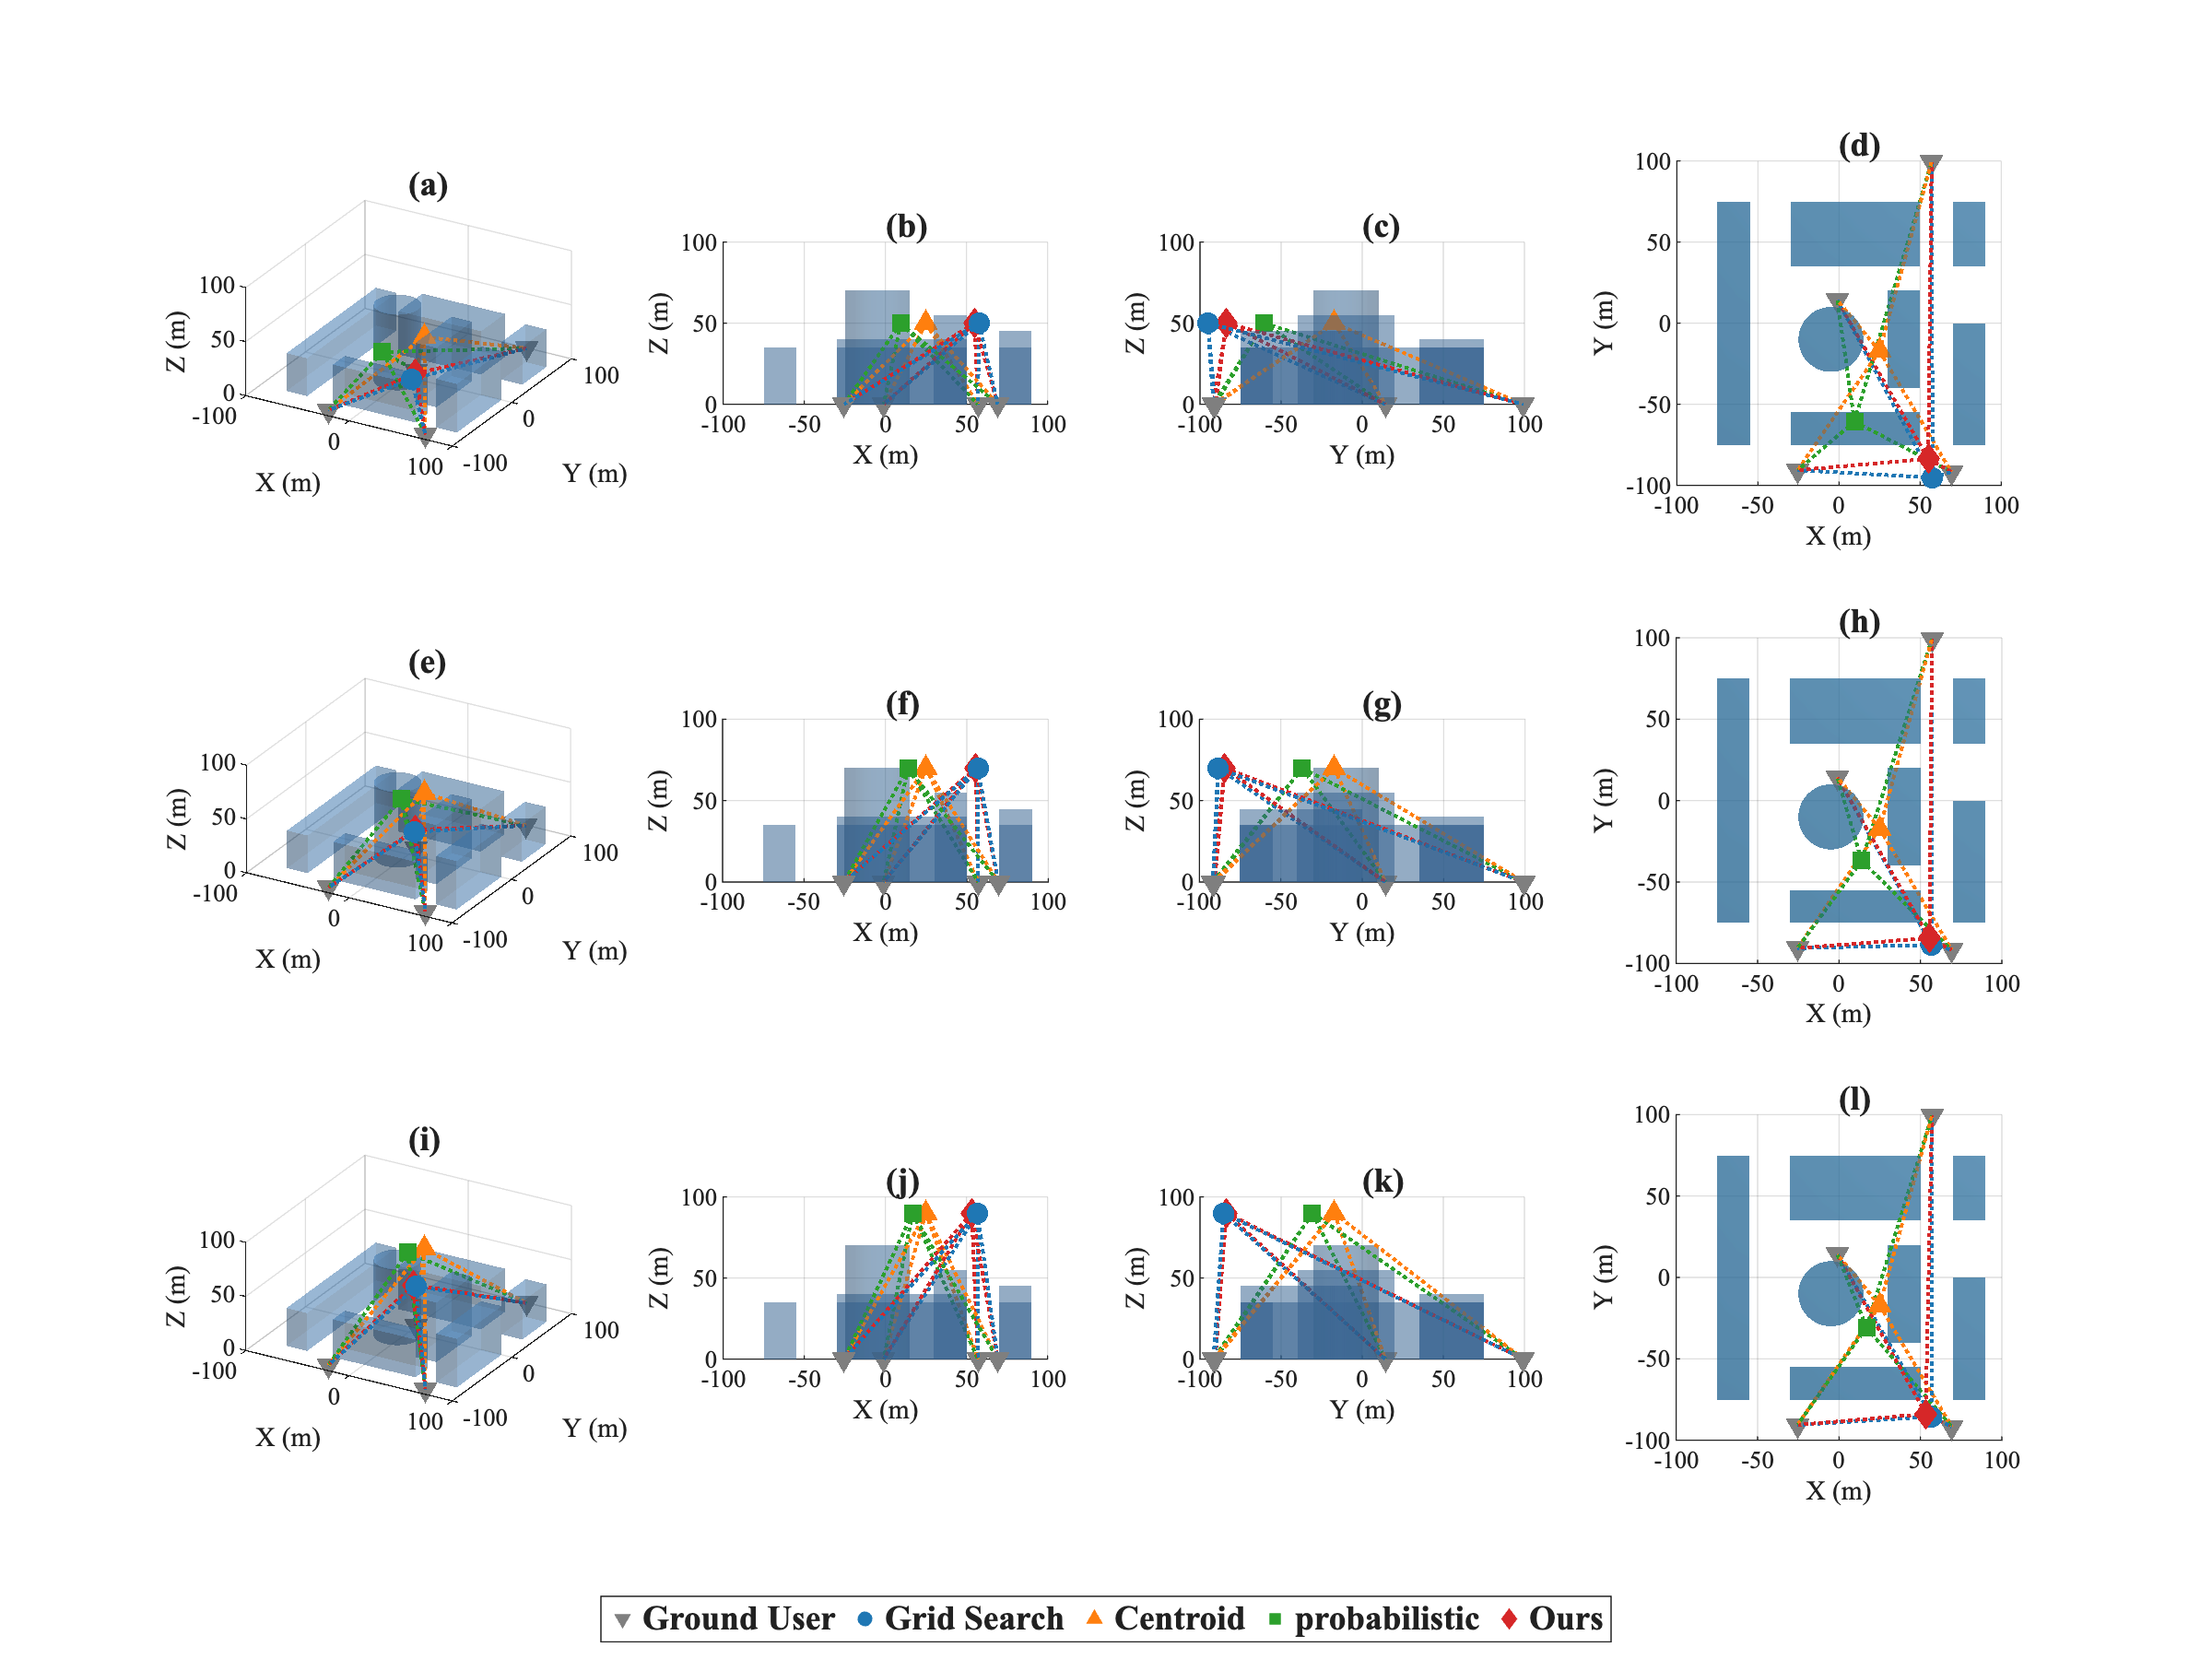

% 1. 초기 설정
clear; clc; close all;
set(groot, 'DefaultAxesFontName', 'Times New Roman');
set(groot, 'DefaultTextFontName', 'Times New Roman');

% 시각화할 데이터 행 선택 (MATLAB은 1부터 시작)
scenario_index = 14;

%% 2. 데이터 로드 및 추출
% CSV 파일 읽기
data_table = readtable('eval_mode_height_U4_H90.csv');
data_row   = data_table(scenario_index, :);

% 지상 사용자(GUs) 좌표 추출 및 3x4 행렬로 변환
gnd_coords = [data_row.gnd1_x, data_row.gnd1_y, data_row.gnd1_z; ...
              data_row.gnd2_x, data_row.gnd2_y, data_row.gnd2_z; ...
              data_row.gnd3_x, data_row.gnd3_y, data_row.gnd3_z; ...
              data_row.gnd4_x, data_row.gnd4_y, data_row.gnd4_z]'; % 3x4

% UAV 위치 좌표 추출
uav_positions = struct( ...
  'BF',       [data_row.bf_x,   data_row.bf_y,   data_row.bf_z], ...
  'Centroid', [data_row.cent_x, data_row.cent_y, data_row.cent_z], ...
  'Prob',     [data_row.prob_x, data_row.prob_y, data_row.prob_z], ...
  'Ours',     [data_row.ours_x, data_row.ours_y, data_row.ours_z] ...
);

%% 3. 3D 시각화 창 설정
figure('Position', [100, 100, 1200, 900]);
ax = axes('Projection', 'perspective');
hold(ax, 'on'); grid(ax, 'on'); axis(ax, 'equal');

%% 4. 장애물(STL 파일) 렌더링
file_names = {'mesh0.stl','mesh1.stl','mesh2.stl','mesh3.stl','mesh4.stl','mesh5.stl','mesh6.stl'};
object_color = [0.7 0.7 0.7];
object_alpha = 0.5;

for i = 1:length(file_names)
  try
    fv = stlread(file_names{i});
    patch(ax, 'Faces', fv.ConnectivityList, 'Vertices', fv.Points, ...
      'FaceColor', object_color, 'EdgeColor', 'none', 'FaceAlpha', object_alpha);
  catch ME
    warning('Could not load STL file: %s. Skipping. Error: %s', file_names{i}, ME.message);
  end
end

%% 5. 지상 사용자(GUs) 및 UAV 위치 플로팅
scatter3(ax, gnd_coords(1,:), gnd_coords(2,:), gnd_coords(3,:), ...
  100, 'r', 'filled', 'DisplayName', 'Ground Users');

uav_names = fieldnames(uav_positions);
colors = {'g','b','c','m'};
markers = {'^','s','p','d'};
uav_plots = gobjects(length(uav_names), 1);

for i = 1:length(uav_names)
  name = uav_names{i};
  pos  = uav_positions.(name);
  uav_plots(i) = scatter3(ax, pos(1), pos(2), pos(3), ...
    150, colors{i}, 'filled', 'Marker', markers{i}, 'DisplayName', name);
end

%% 6. UAV와 GUs 간의 라인 연결
for i = 1:length(uav_names)
  uav_pos = uav_positions.(uav_names{i});
  line_color = colors{i};
  for k = 1:size(gnd_coords, 2)
    gu_pos = gnd_coords(:, k);
    plot3(ax, [uav_pos(1), gu_pos(1)], [uav_pos(2), gu_pos(2)], [uav_pos(3), gu_pos(3)], ...
      'Color', line_color, 'LineWidth', 1.5, 'LineStyle', '--');
  end
end

%% 7. 플롯 최종 설정
xlim(ax, [-100, 100]); ylim(ax, [-100, 100]); zlim(ax, [0, 100]);
view(30, 25); lighting gouraud; camlight('headlight');
material([0.3 0.6 0.1 20 1]);

title(['3D Visualization of UAV Positions (Scenario ', num2str(scenario_index), ')']);
xlabel('X'); ylabel('Y'); zlabel('Z');
legend(uav_plots, 'Location', 'northeast');
hold(ax, 'off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 1. 초기 설정 (멀티 뷰/높이 그림)
clear; clc; close all;

% 시각화할 데이터 행 선택
scenario_index = 205;

% 처리할 높이 및 뷰 목록
heights     = [50, 70, 90];
view_angles = {[30, 25], [0, 0], [90, 0], [0, 90]};
stl_files   = {'mesh0.stl','mesh1.stl','mesh2.stl','mesh3.stl','mesh4.stl','mesh5.stl','mesh6.stl'};

%% 2. 컬러맵 정의 (tab10)
tab10 = [ ...
  31, 119, 180; 255, 127,  14;  44, 160,  44; 214,  39,  40; ...
 148, 103, 189; 140,  86,  75; 227, 119, 194; 127, 127, 127; ...
 188, 189,  34;  23, 190, 207] / 255;

colors.BF         = tab10(1, :);
colors.Centroid   = tab10(2, :);
colors.Prob       = tab10(3, :);
colors.Ours       = tab10(4, :);
colors.GroundUser = tab10(8, :);

colors.Obstacle_default = [0.3216 0.6667 1.0000];
colors.Obstacle_XY      = [0.1216 0.4667 0.7059];

%% 3. 모든 CSV 데이터 미리 불러오기
data_tables = cell(1, length(heights));
for h = 1:length(heights)
  try
    filename = sprintf('eval_mode_height_U4_H%d.csv', heights(h));
    data_tables{h} = readtable(filename);
  catch
    data_tables{h} = [];
  end
end

%% 4. 3x4 시각화 창 및 레이아웃 설정  <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<< 변경
figure('Position', [50, 50, 1200, 900], 'Color', 'w');
t = tiledlayout(3, 4, 'TileSpacing', 'compact', 'Padding', 'normal');

%% 5. 뷰와 높이에 대한 이중 루프 실행  <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<< 순서 변경
num_heights = length(heights);
num_views   = length(view_angles);
plot_labels = 'a':'l';

for h = 1:num_heights           % 행: 높이(H=50/70/90)
  for v = 1:num_views           % 열: 뷰(3D, X-Y, Y-Z, X-Z 등 지정된 순서)
    plot_index = (h - 1) * num_views + v;   % 3x4 인덱싱
    ax = nexttile;

    if isempty(data_tables{h})
      axis(ax, 'off'); continue;
    end

    data_table = data_tables{h};
    data_row   = data_table(scenario_index, :);

    gnd_coords = [data_row.gnd1_x, data_row.gnd1_y, data_row.gnd1_z; ...
                  data_row.gnd2_x, data_row.gnd2_y, data_row.gnd2_z; ...
                  data_row.gnd3_x, data_row.gnd3_y, data_row.gnd3_z; ...
                  data_row.gnd4_x, data_row.gnd4_y, data_row.gnd4_z]';

    uav_positions = struct( ...
      'BF',       [data_row.bf_x,   data_row.bf_y,   data_row.bf_z], ...
      'Centroid', [data_row.cent_x, data_row.cent_y, data_row.cent_z], ...
      'Prob',     [data_row.prob_x, data_row.prob_y, data_row.prob_z], ...
      'Ours',     [data_row.ours_x, data_row.ours_y, data_row.ours_z] ...
    );

    if v == 4
      current_object_color = colors.Obstacle_XY;
    else
      current_object_color = colors.Obstacle_default;
    end

    plot_scene_final(ax, stl_files, gnd_coords, uav_positions, current_object_color, colors, v);

    current_view = view_angles{v};
    view(ax, current_view(1), current_view(2));

    title(ax, ['(', plot_labels(plot_index), ')'], ...
      'HorizontalAlignment','left','VerticalAlignment','baseline', ...
      'FontSize',14,'FontWeight','bold');
  end
end

%% 6. 공통 범례 생성
lgd_ax = axes('Position', [0, 0, 1, 1], 'Visible', 'off'); hold(lgd_ax, 'on');
h_gnd  = scatter(lgd_ax, NaN, NaN, 150, colors.GroundUser, 'filled', 'Marker', 'v');
h_bf   = scatter(lgd_ax, NaN, NaN, 150, colors.BF,       'filled', 'Marker', 'o');
h_cent = scatter(lgd_ax, NaN, NaN, 150, colors.Centroid, 'filled', 'Marker', '^');
h_prob = scatter(lgd_ax, NaN, NaN, 150, colors.Prob,     'filled', 'Marker', 's');
h_ours = scatter(lgd_ax, NaN, NaN, 150, colors.Ours,     'filled', 'Marker', 'd');
hold(lgd_ax, 'off');

lgd = legend([h_gnd, h_bf, h_cent, h_prob, h_ours], ...
  {'Ground User', 'Grid Search', 'Centroid', 'probabilistic', 'Ours'}, ...
  'Orientation', 'horizontal', 'FontSize', 14, 'FontWeight', 'bold');
lgd.Position(1) = 0.5 - lgd.Position(3)/2;
lgd.Position(2) = 0.01;

% exportgraphics(gcf, 'figure_final_multi-light.png', 'Resolution', 600);

%% 로컬 함수: 논문용 3D 씬을 그리는 함수
function plot_scene_final(ax, stl_files, gnd_coords, uav_positions, object_color, colors, v)
  hold(ax, 'on');

  if v == 4
    object_alpha = 0.5;
  else
    object_alpha = 0.3;
  end

  for i = 1:length(stl_files)
    try
      fv = stlread(stl_files{i});
      patch(ax, 'Faces', fv.ConnectivityList, 'Vertices', fv.Points, ...
        'FaceColor', object_color, 'EdgeColor', 'none', 'FaceAlpha', object_alpha, ...
        'FaceLighting', 'flat');
    catch
    end
  end

  scatter3(ax, gnd_coords(1,:), gnd_coords(2,:), gnd_coords(3,:), ...
    75, colors.GroundUser, 'filled', 'Marker', 'v');

  uav_names = fieldnames(uav_positions);
  markers   = {'o','^','s','d'};
  for i = 1:length(uav_names)
    name = uav_names{i};
    pos  = uav_positions.(name);
    scatter3(ax, pos(1), pos(2), pos(3), 75, colors.(name), 'filled', 'Marker', markers{i});
  end

  for i = 1:length(uav_names)
    name = uav_names{i};
    uav_pos = uav_positions.(name);
    for k = 1:size(gnd_coords, 2)
      gu_pos = gnd_coords(:, k);
      plot3(ax, [uav_pos(1), gu_pos(1)], [uav_pos(2), gu_pos(2)], [uav_pos(3), gu_pos(3)], ...
        'Color', colors.(name), 'LineWidth', 1.5, 'LineStyle', ':');
    end
  end

  grid(ax, 'on'); axis(ax, 'equal');
  xlim(ax, [-100, 100]); ylim(ax, [-100, 100]); zlim(ax, [0, 100]);
  xlabel(ax, 'X (m)'); ylabel(ax, 'Y (m)'); zlabel(ax, 'Z (m)');

  lighting(ax, "flat");
  if v == 2 || v == 3
    light(ax, 'Position', [100 -100, -200], 'Style', 'infinite');
  else
    camlight('infinite');
  end

  hold(ax, 'off');
end

set(gcf,'Renderer','opengl');
print('./results','-depsc','-opengl','-r600')